# OPTIMIZEKNN

Use hyperparameter optimization to automatically tune *k*-NN models for the heart disease data.

## Load data

load heartdisease

## Divide the data into training and validation sets

rng(1234)
part = cvpartition(heartdataNum.HeartDisease,'Holdout',0.2);
tridx = training(part);
dataTrain = heartdataNum(tridx,:);
dataTest = heartdataNum(~tridx,:);

## Train a *k*-NN model with default properties

m = fitcknn(dataTrain,'HeartDisease');
resubLoss(m)

ans = 0

loss(m,dataTest)

ans = 0.3413

## Turn on hyperparameter optimization

Setting '`OptimizeHyperparamters`' to '`auto`' will optimize these *k*-NN properties:

- `NumNeighbors`

- `Distance`

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.30409 |     0.10418 |     0.30409 |     0.30409 |           17 |    minkowski |
|    2 | Accept |     0.36257 |     0.16019 |     0.30409 |     0.30642 |           69 |      jaccard |
|    3 | Accept |     0.37427 |     0.12269 |     0.30409 |     0.32724 |            2 |   seuclidean |
|    4 | Accept |     0.33041 |     0.11669 |     0.30409 |     0.31852 |            4 |       cosine |
|    5 | Accept |     0.30409 |     0.13264 |     0.30409 |      0.3041 |           17 |    minkowski |
|    6 | Accept |     0.31579 |     0.11063 |     0.30409 |     

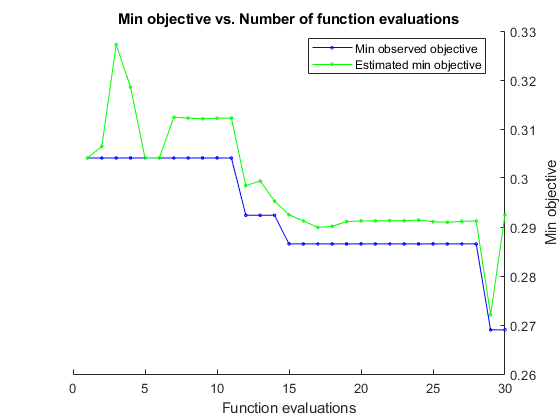

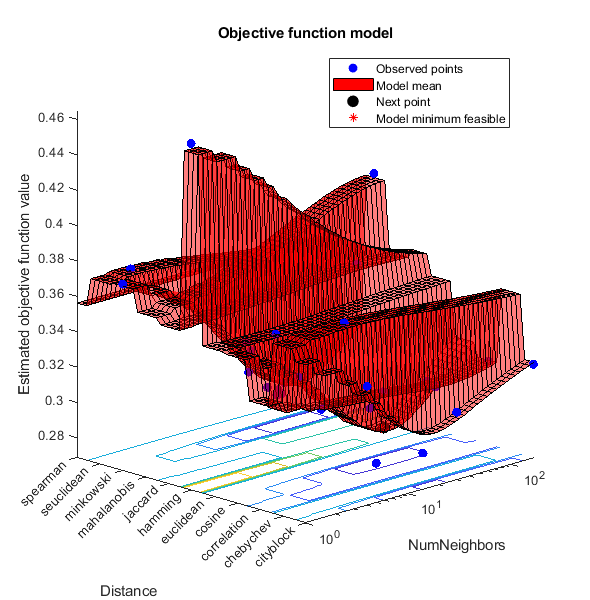

m = fitcknn(dataTrain,'HeartDisease','OptimizeHyperparameters','auto');

The command-line output contains information on the evaluated property values and the hyperparameters chosen for the final model.

m.Distance

ans = 'minkowski'

m.NumNeighbors

ans = 36

The first plot shows the best objective function against the iteration number. The second plot is a model of the objective function against the parameters. You can hide these plots with the '`ShowPlots`' argument.

resubLoss(m)

ans = 0.2749

loss(m,dataTest)

ans = 0.1883

## Change optimization options

Make cross validation partition

part = cvpartition(dataTrain.HeartDisease,'KFold',10);

Change the validation to use '`part`' and decrease the number of objective evaluations.

opt = struct('CVPartition',part,'MaxObjectiveEvaluations',20);

Setting '`OptimizeHyperparamters`' to '`all`' will optimize these *k*-NN properties:

- `NumNeighbors`

- `Distance`

- `DistanceWeight`

- `Exponent`

- `Standardize`

|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance | DistanceWeig-|     Exponent |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ht           |              |              |
|==================================================================================================================================================|
|    1 | Best   |     0.36842 |     0.25224 |     0.36842 |     0.36842 |           98 |      jaccard | squaredinver |            - |        false |
|    2 | Best   |     0.29532 |     0.20964 |     0.29532 |     0.29823 |           96 |  mahalanobis |        equal |            - |        false |
|    3 | Accept |     0.35965 |     0.26276 |     0.29532 |     0.29811 |            2 |       cosine |   

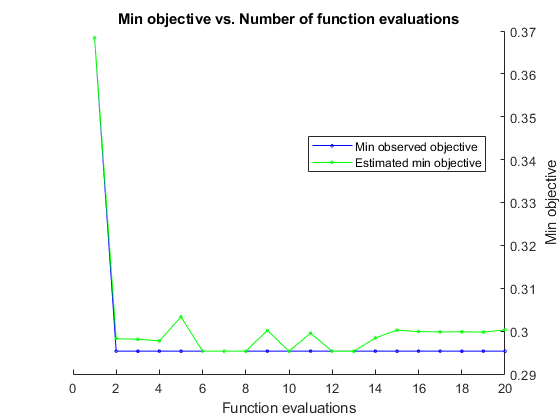

m = fitcknn(dataTrain,'HeartDisease','OptimizeHyperparameters','all','HyperparameterOptimizationOptions',opt);

Note that there is only one plot displayed. You will only see the second plot if there are one or two optimization parameters, and if '`Optimizer`' is set to '`bayesopt`'.

resubLoss(m)

ans = 0.3099

loss(m,dataTest)

ans = 0.1765